# Chessboard Calibration

## Thermal

     2



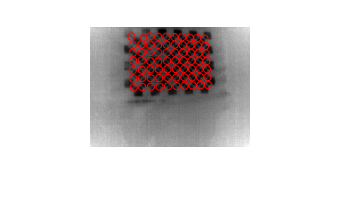

     3



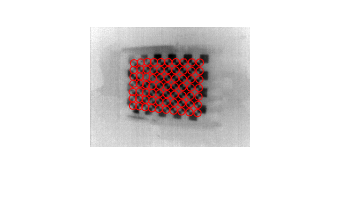

     7



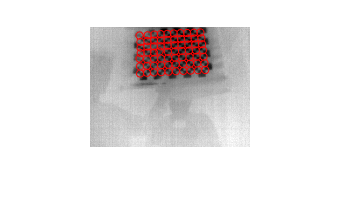

     8



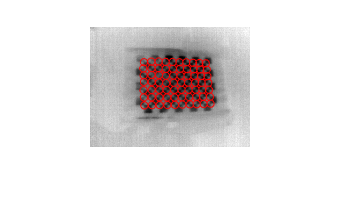

     9



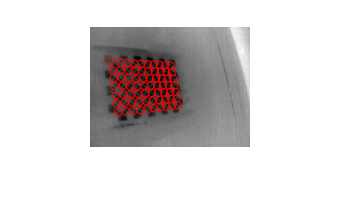

    11



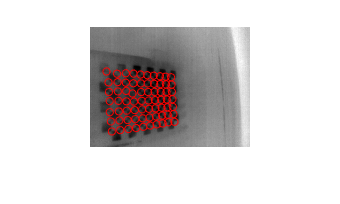

    12



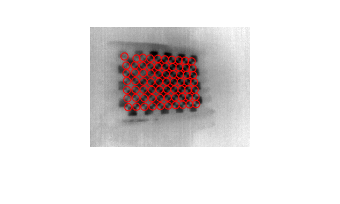

    13



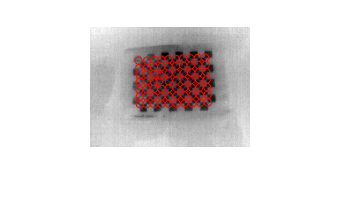

    15



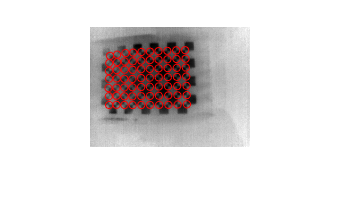

    16



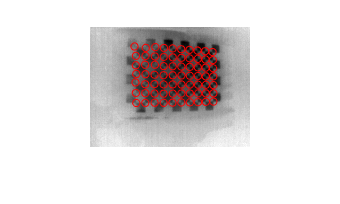

    43



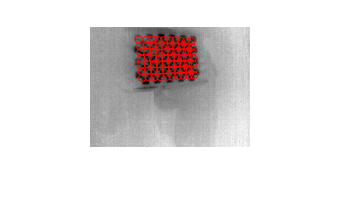

    46



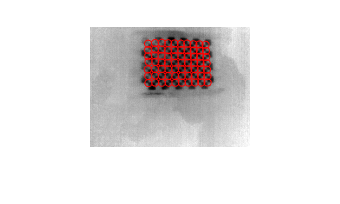

    47



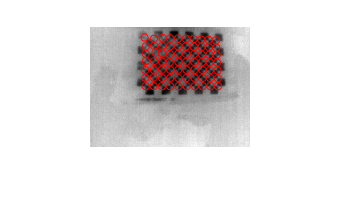

    48



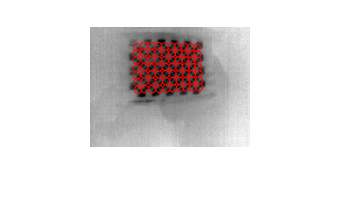

thermImgSet = imageSet('Thermal');

ImgT = [];

boardSize = [8 11];
gamma = 1.65;

for i=1:length(thermImgSet.ImageLocation)
    Itmp = imread(thermImgSet.ImageLocation{i});

    max_v = max(Itmp(:));
    min_v = min(Itmp(:));

    Itmp = (double(Itmp) - double(min(Itmp(:)))) ./ double(max_v - min_v);
    Itmp = imcomplement(Itmp);
    Itmp = Itmp.^gamma;
    ImgT(:,:,:,i) = Itmp;
    
    imageSize = [size(Itmp,1),size(Itmp,2)];
end

[imagePoints,detectedBoardSize,imagesUsed] = detectCheckerboardPoints(ImgT,'MinCornerMetric',1e-10,'PartialDetections',false);

count = 1;
for i=1:length(imagesUsed)
    if imagesUsed(i) == true
        disp(i);
        figure;
        imshow(ImgT(:,:,:,i));
        hold on;
        plot(imagePoints(:,1,count),imagePoints(:,2,count),'ro');
        count = count + 1;
        hold off;
    end
end


disp('Image used');

Image used


disp(count-1);

    14



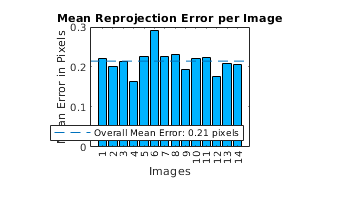


if ~isequal(boardSize,detectedBoardSize)
    disp('Pattern not succefully detected');
    return;
end

squareSize = 20;
worldPoints = generateCheckerboardPoints(boardSize,squareSize);

[params,pused] = estimateCameraParameters(imagePoints,worldPoints,'ImageSize',imageSize);
showReprojectionErrors(params);

## Visible

     2



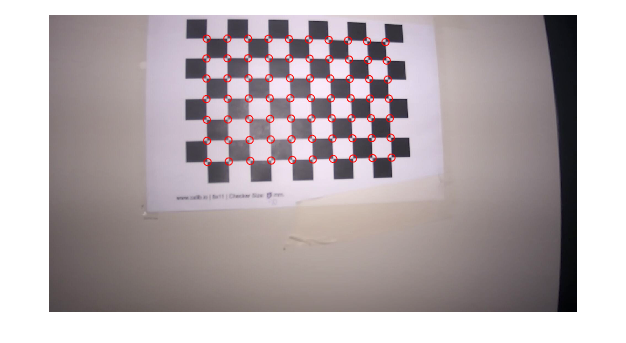

     3



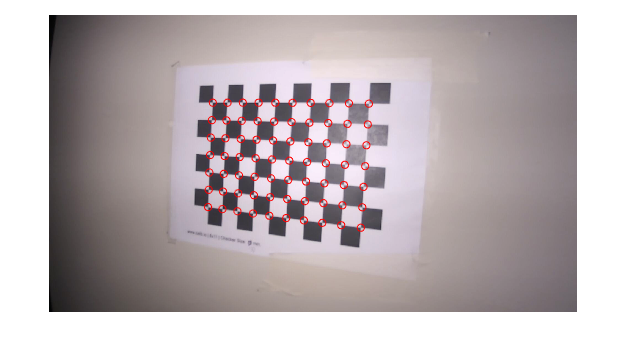

     7



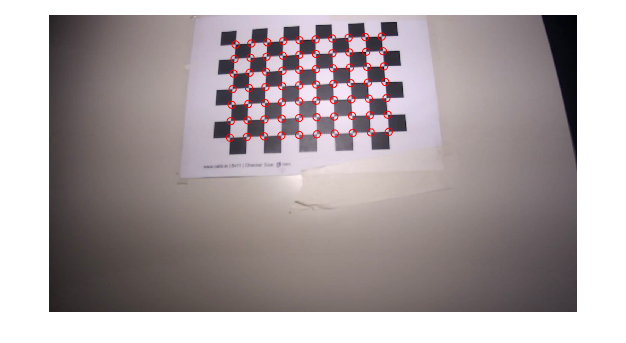

     8



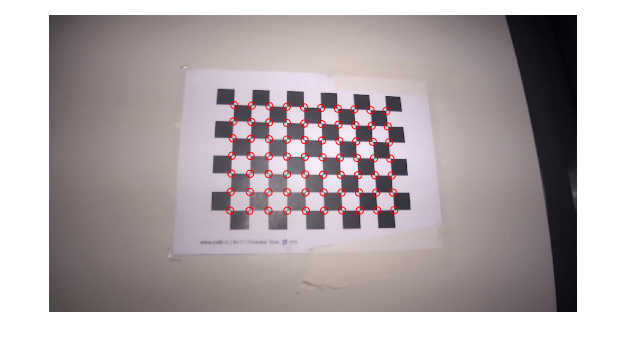

     9



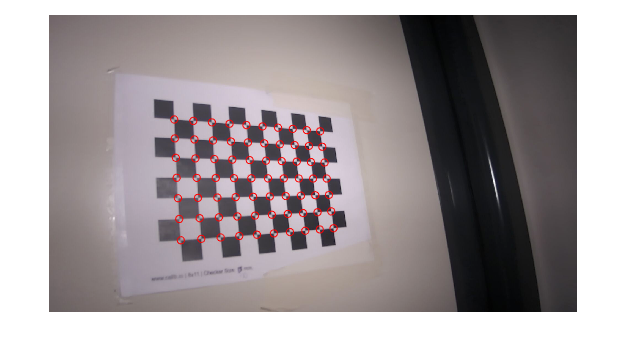

    11



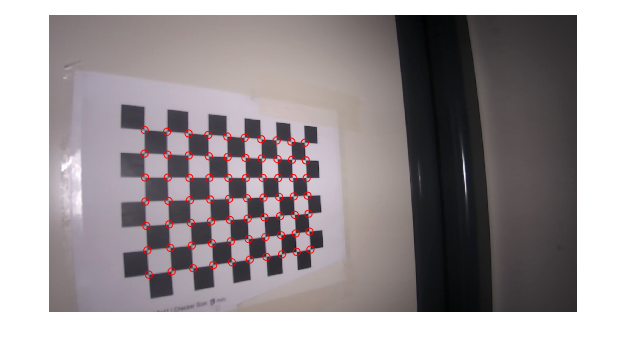

    12



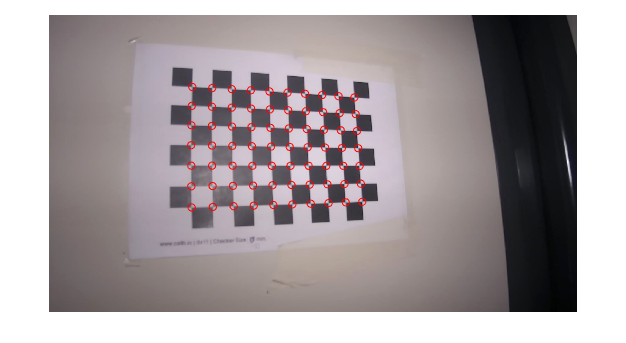

    13



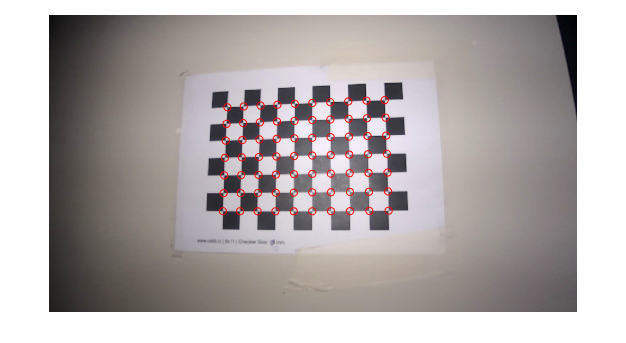

    15



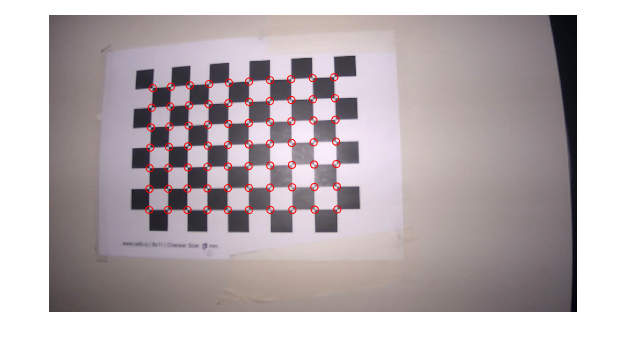

    16



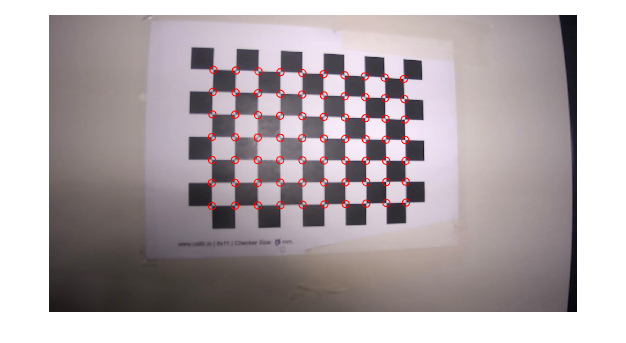

    43



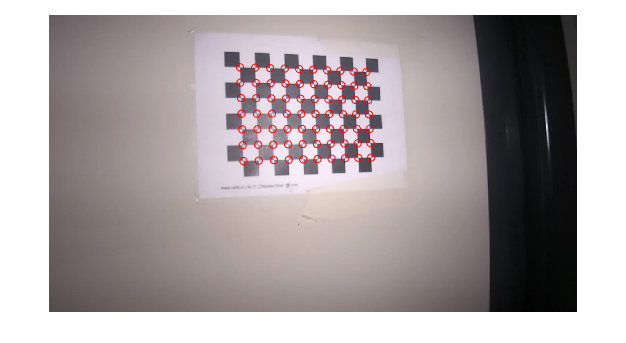

    46



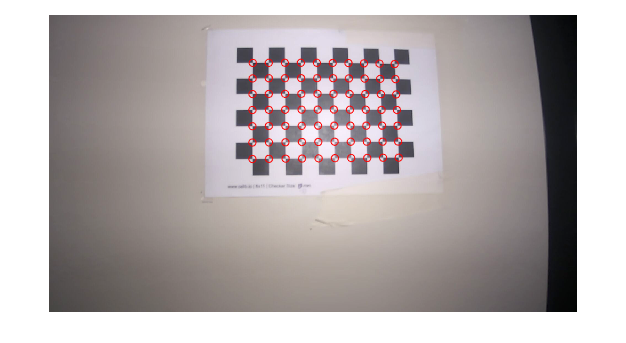

    47



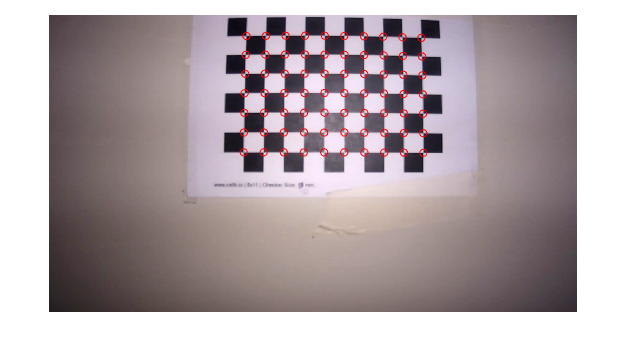

    48



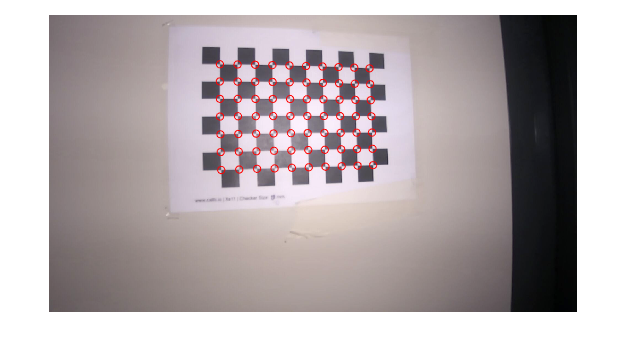

visImgSet = imageSet('Visible');

ImgV = [];
boardSize = [8 11];

for i=1:length(visImgSet.ImageLocation)
    if ismember(i,find(imagesUsed == 1))
        Itmp = imread(visImgSet.ImageLocation{i});
        Itmp = (double(Itmp) - double(min(Itmp(:)))) ./ (double(max(Itmp(:))) - double(min(Itmp(:))));
        ImgV(:,:,:,i) = Itmp;
        imageSizeV = [size(Itmp,1),size(Itmp,2)];    
    end
end

[imagePointsV,detectedBoardSize,imagesUsedV] = detectCheckerboardPoints(ImgV,'PartialDetections',false);

count = 1;
for i=1:length(imagesUsedV)
    if imagesUsed(i) == true
        disp(i);
        figure;
        imshow(ImgV(:,:,:,i));
        hold on;
        plot(imagePointsV(:,1,count),imagePointsV(:,2,count),'ro');
        count = count + 1;
        hold off;
    end
end

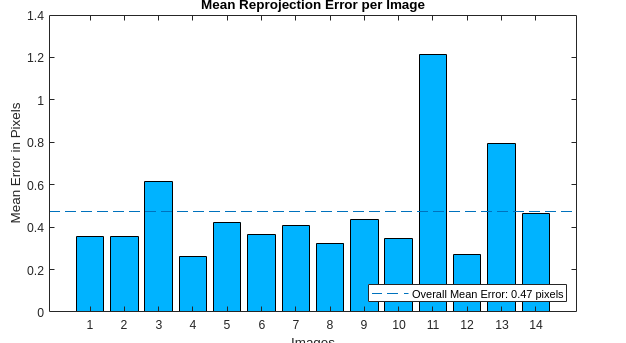


if ~isequal(boardSize,detectedBoardSize)
    disp('Pattern not succefully detected');
    return;
end

squareSize = 20;
worldPoints = generateCheckerboardPoints(boardSize,squareSize);

[paramsV,pusedV] = estimateCameraParameters(imagePointsV,worldPoints,'ImageSize',imageSizeV);
showReprojectionErrors(paramsV);

## Stereo calibration output

sImagePoints = [];

sImagePoints(:,:,:,1) = imagePointsV;
sImagePoints(:,:,:,2) = imagePoints;

sImagePoints(:,:,[11 13],:) = [];

[SChessboardcameraParams, SChessboardPairUsed, SChessboardestimationErrors] = estimateCameraParameters(sImagePoints, worldPoints,'NumRadialDistortionCoefficients',3);

displayErrors(SChessboardestimationErrors, SChessboardcameraParams);


			Standard Errors of Estimated Stereo Camera Parameters
			-----------------------------------------------------

Camera 1 Intrinsics
-------------------
Focal length (pixels):   [ 1381.9685 +/- 10.4604    1382.7284 +/- 9.9298  ]
Principal point (pixels):[  974.9510 +/- 7.6968      545.4070 +/- 7.1780  ]
Radial distortion:       [   -0.2050 +/- 0.0227        0.1795 +/- 0.1802       -0.2270 +/- 0.4140  ]

Camera 1 Extrinsics
-------------------
Rotation vectors:
                         [   -0.0416 +/- 0.0060       -0.1596 +/- 0.0057       -0.0304 +/- 0.0010  ]
                         [    0.0312 +/- 0.0056        0.3603 +/- 0.0059        0.0643 +/- 0.0014  ]
                         [   -0.2092 +/- 0.0060        0.0810 +/- 0.0055       -0.0204 +/- 0.0014  ]
                         [   -0.2679 +/- 0.0060       -0.1602 +/- 0.0062       -0.0050 +/- 0.0012  ]
                         [   -0.2557 +/- 0.0057       -0.6110 +/- 0.0059       -0.0583 +/- 0.0017  ]
                         [ 

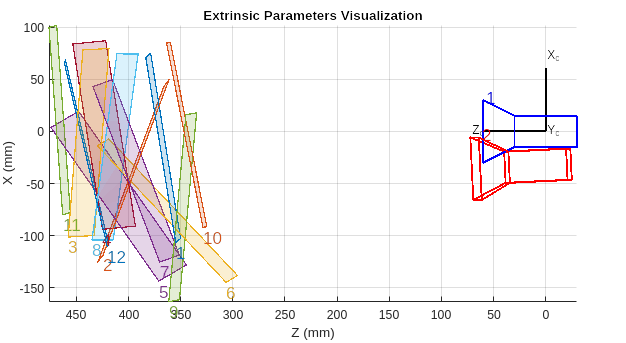

showExtrinsics(SChessboardcameraParams);